% Sinais vindos da simulação
entrada = wdesejada.signals.values;        %% degrau
velocidade = wreal.signals.values;         %% saída
tempo = wreal.time;                        %% tempo

% Ajuste de parâmetros
x0 = [1 1]; %% condição inicial
X = fminsearch(@(x) ErroQuadratico(x, entrada, velocidade, tempo'), x0)

X =   137.8135    6.0609


% Parâmetros usados no modelo
Km = X(1);
pm = X(2);

% Km = 137.8
% pm = 6.061

% Função de transferência do modelo do motor
Gp = tf(Km, [1 pm]) %% função transferência do modelo


Gp =
 
    137.8
  ---------
  s + 6.061
 
Continuous-time transfer function.



ym = lsim(Gp, entrada, tempo); %% saida do modelo para a mesma entrada

%backup do motor
Km = 137.8
pm = 6.061

% Função de transferência do modelo do motor
Gp = tf(Km, [1 pm]) %% função transferência do modelo

% Definição de especificações desejadas
tp_desejado = 0.1;  % Tempo de pico desejado, em segundos
Mp_desejado = 0.25;   % Overshoot máximo permitido, em porcentagem

% teoricos
zeta = sqrt((log(Mp_desejado)^2) / (pi^2 + log(Mp_desejado)^2));
ang = rad2deg(acos(zeta));
Wn =  pi / (tp_desejado * sqrt(1 - zeta^2));

sigma = zeta*Wn

sigma = 13.8629

Wd = sin(deg2rad(ang))* Wn

Wd = 31.4159

ts = 4 / sigma;

% Substituindo S na equacao
S = -sigma -1j*Wd

S = -13.8629 - 31.4159i

Gg = (Km * (S + sigma)) / (S * (S + pm));
K = -1/Gg;  % Igualando equacao a -1

modulo = abs(K);
fase = rad2deg(angle(K));

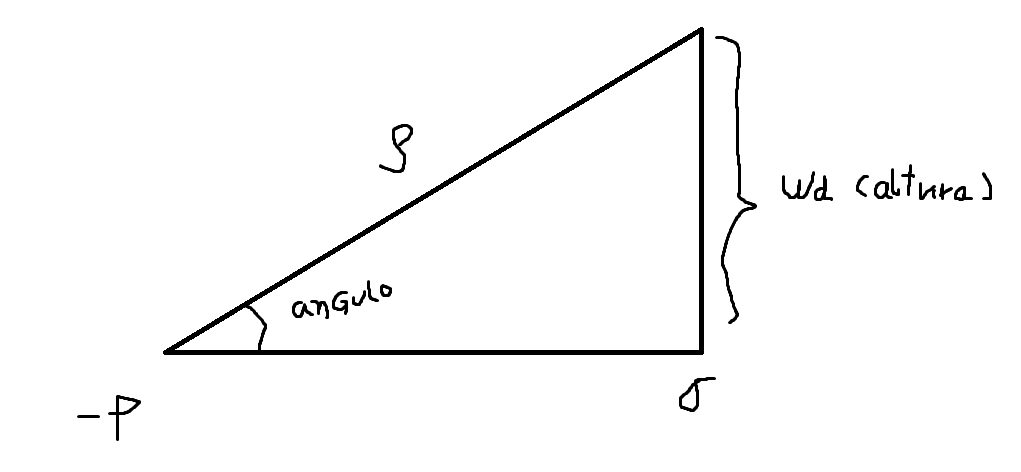

roP = Wd/sin(fase);

K = modulo * roP

K = 8.7799

z = sqrt(roP^2 - Wd^2)

z = 13.5113

p = z + sigma

p = 27.3743

% Gc
% Definindo o controlador com parâmetros otimizados
Gc = tf([K K*z], [1 p])


Gc =
 
  8.78 s + 118.6
  --------------
    s + 27.37
 
Continuous-time transfer function.



% Sistema em malha fechada com o controlador
G_malha_fechada = feedback(Gc * Gp, 1)


G_malha_fechada =
 
     1210 s + 1.635e04
  -----------------------
  s^2 + 1243 s + 1.651e04
 
Continuous-time transfer function.



% Análise da resposta do sistema em malha fechada
info = stepinfo(G_malha_fechada);
fprintf('Tempo de Pico (tp): %.4f s\n', info.PeakTime);

Tempo de Pico (tp): 0.0086 s


fprintf('Overshoot (Mp): %.2f %%\n', info.Overshoot);

Overshoot (Mp): 0.00 %


% Verifica se as especificações são atendidas
if info.PeakTime <= tp_desejado && info.Overshoot <= Mp_desejado
    fprintf('Especificações atendidas para tp e Mp.\n');
else
    fprintf('Especificações NÃO atendidas. Ajuste K, z, ou p.\n');
end

Especificações atendidas para tp e Mp.


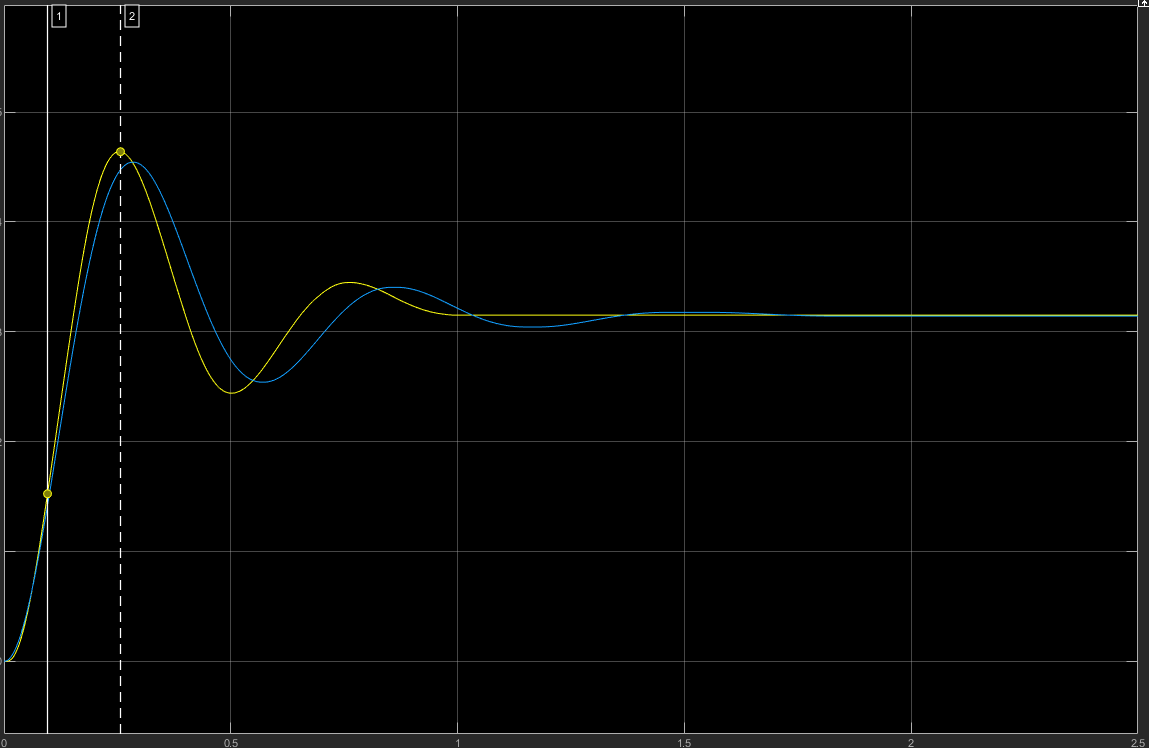

function [Eq] = ErroQuadratico(X,u,y,t)

Km= X(1);
pm = X(2);

%%% Modelo

Gp = tf(Km, [1 pm]);

%%% Saida do modelo

ym = lsim(Gp, u, t);

%%% Erro quadrático

Eq = sum((y-ym).^2); %% cálculo do erro

% plot(t,y,t,ym,"linewidth", 2)

end